## Compute a single statistic

%define the variance with no randomization
clear;
sigma_0 = 0.015

sigma_0 = 0.0150


%define the variance with randomization
sigma_s = 0.1;
sigma_1 = sigma_0 + sigma_s

sigma_1 = 0.1150


PFA = 1e-2;
N = 11;

%compute the threshold
eta = chi2inv(1-PFA,N) * sigma_0 / N

eta = 0.0337

PD = chi2cdf(N * eta / (sigma_1),N,'upper')

PD = 0.9874

## Plot PD vs PFA for a single sigma

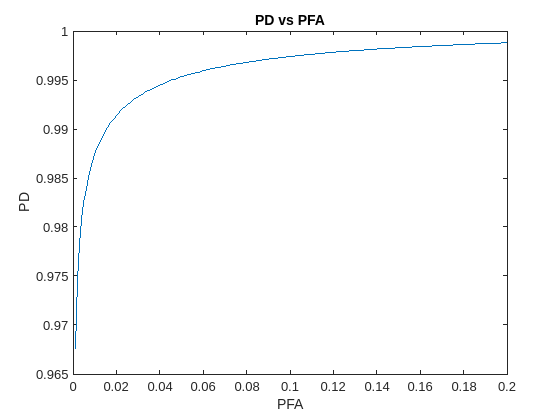

PFA = 1e-3:1e-3:2e-1;
eta = chi2inv(1-PFA,N) * sigma_0 / N;

PD = chi2cdf(N * eta / (sigma_1),N,'upper');

plot(PFA,PD)
title("PD vs PFA")
xlabel("PFA")
ylabel("PD")

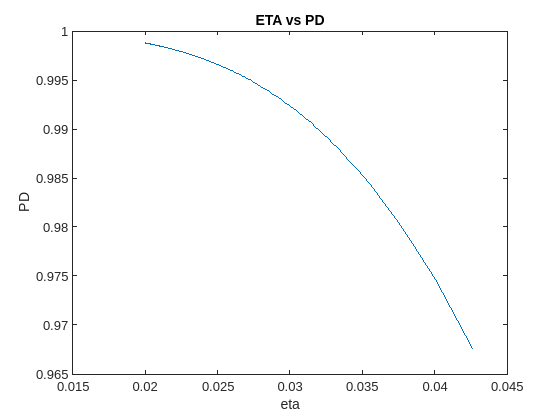

plot(eta,PD)
title("ETA vs PD")
xlabel("eta")
ylabel("PD")

## Plot PD vs various Sigma Values - specific PFA value

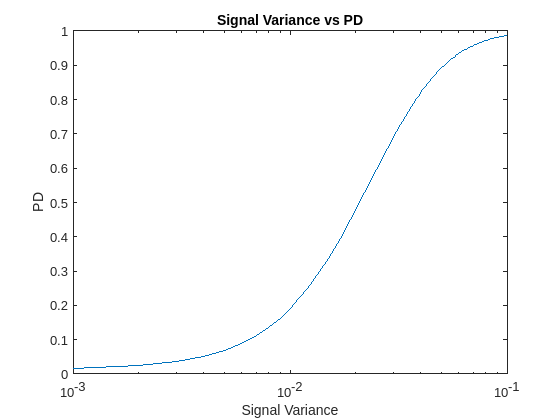

sigma_s = 1e-3:1e-3:1e-1;
sigma_1 = sigma_0 + sigma_s;

PFA = 1e-2;

%compute the threshold
eta = chi2inv(1-PFA,N) * sigma_0 / N;
PD = chi2cdf(N * eta ./ sigma_1,N,'upper');

semilogx(sigma_s,PD);
title("Signal Variance vs PD")
xlabel("Signal Variance")
ylabel("PD")